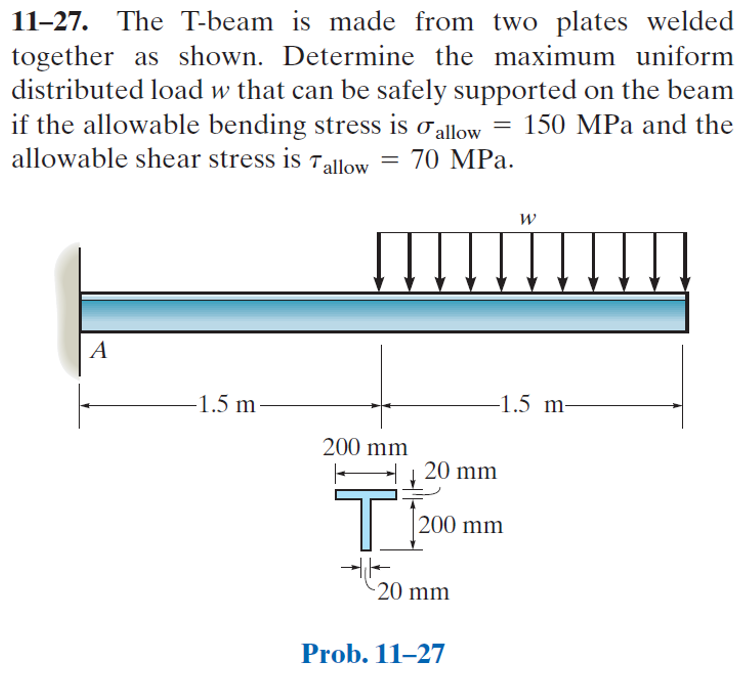

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-27P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-27P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

wo = sym('wo');
wo_max = default_struct('bending', 'shear', 'limit');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'moment', 'Ma', 0);
b = b.add('distributed', 'force', -wo, [1.5 3]*u.m);
b.L = 3*u.m;

# section properties

yc = [100 210]*u.mm;
Ac = [20*200 200*20]*u.mm^2;
Ic = [20*200^3 200*20^3]/12*u.mm^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{429496729600000000000\,\mathrm{wo}\,x^{2}\,\left(4\,x-27\,m\right)}{258843362372266671\,\text{E}}\,\frac{1}{m^{3}} & \text{ if }x\leq \frac{3}{2}\,m\\ -\frac{53687091200000000000\,\mathrm{wo}\,\left(16\,x^{4}-192\,x^{3}\,m+864\,x^{2}\,m^{2}-216\,x\,m^{3}+81\,m^{4}\right)}{776530087116800013\,\text{E}}\,\frac{1}{m^{4}} & \text{ if }\frac{3}{2}\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{858993459200000000000\,\mathrm{wo}\,x\,\left(2\,x-9\,m\right)}{86281120790755557\,\text{E}}\,\frac{1}{m^{3}} & \text{ if }x\leq \frac{3}{2}\,m\\ -\frac{429496729600000000000\,\mathrm{wo}\,\left(8\,x^{3}-72\,x^{2}\,m+216\,x\,m^{2}-27\,m^{3}\right)}{776530087116800013\,\text{E}}\,\frac{1}{m^{4}} & \text{ if }\frac{3}{2}\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{3\,\mathrm{wo}\,\left(4\,x-9\,m\right)}{8}\,m & \text{ if }x<\frac{3}{2}\,m\\ -\frac{\mathrm{wo}\,{\left(x-3\,m\right)}^{2}}{2} & \text{ if }\frac{3}{2}\,m\leq x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{3\,\mathrm{wo}}{2}\,m & \text{ if }x<\frac{3}{2}\,m\\ -\mathrm{wo}\,\left(x-3\,m\right) & \text{ if }\frac{3}{2}\,m\leq x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<\frac{3}{2}\,m\\ -\mathrm{wo} & \text{ if }\frac{3}{2}\,m\leq x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ma} & \frac{27\,\mathrm{wo}}{8}\,m^{2}\\ \mathrm{Ra} & \frac{3\,\mathrm{wo}}{2}\,m \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

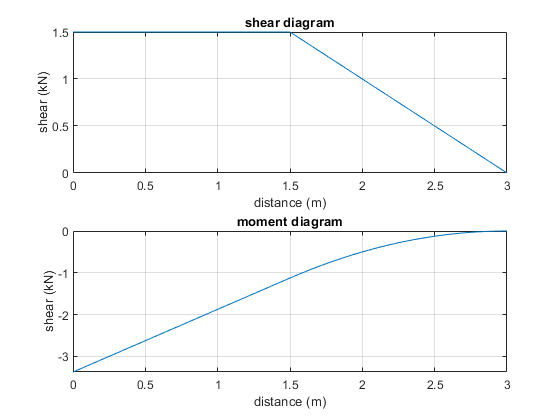

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'}, wo, 1);

# maximum loads

M_max(wo) = -m(0)

$$M\_max(wo) = \frac{27\,\mathrm{wo}}{8}\,m^{2}$$

V_max(wo) = v(0)

$$V\_max(wo) = \frac{3\,\mathrm{wo}}{2}\,m$$

# maximum bending stresses

C = symmax([yn 220*u.mm-yn]);
b.I = rewrite(b.I, u.mm);
sigma_max = rewrite(M_max*C/b.I, u.m)

$$sigma\_max(wo) = \frac{399431958528000000000\,\mathrm{wo}}{28760373596918519}\,\frac{1}{m}$$

Q_max = (yn/2)*(20*u.mm*yn);
t_min = 20*u.mm;
tau_max = rewrite(V_max*Q_max/(b.I*t_min), u.m)

$$tau\_max(wo) = \frac{41274635714560000000\,\mathrm{wo}}{86281120790755557}\,\frac{1}{m}$$

# maximum load intensity due to bending

sigma_allow = 150*u.MPa;
wo_max.bending = rewrite(solve(sigma_max == sigma_allow), [u.kN u.m]);
wo_max_bending = vpa(wo_max.bending, 4) %#ok<NASGU> 

$$wo\_max\_bending = 10.8\,\frac{\mathrm{kN}}{m}$$

# maximum load intensity due to shear

tau_allow = 70*u.MPa;
wo_max.shear = rewrite(solve(tau_max == tau_allow), [u.kN u.m]);
wo_max_shear = vpa(wo_max.shear, 5) %#ok<NASGU> 

$$wo\_max\_shear = 146.33\,\frac{\mathrm{kN}}{m}$$

# limit load intensity

wo_max_vals = [wo_max.bending; wo_max.shear];
loc = (sigma_max(wo_max_vals) <= sigma_allow) & ...
      (tau_max(wo_max_vals) <= tau_allow);
wo_max.limit = wo_max_vals(isAlways(loc));
wo_max_limit = vpa(wo_max.limit, 4) %#ok<NASGU> 

$$wo\_max\_limit = 10.8\,\frac{\mathrm{kN}}{m}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear wo_max_bending;
clear wo_max_shear;
clear wo_max_vals loc wo_max_limit;